Name: Mukesh Aryal

Student ID: 268456

syms y(t);
sol = dsolve(diff(y,t)+10*y == sin(100*t)-cos(100*t),y(0)==1);
ye = matlabFunction(sol)

ye = function_handle with value:
    @(t)exp(t.*-1.0e1).*1.010891089108911-sqrt(2.02e2).*cos(t.*1.0e2-atan(9.0./1.1e1)).*9.900990099009901e-4


f = @(t,y) sin(100*t)-cos(100*t)-10*y;
[tb,yb] = ode45(f,[0,10],1);
errb = ye(tb)-yb;
maxerrb = norm(errb,'inf')

maxerrb = 0.0026

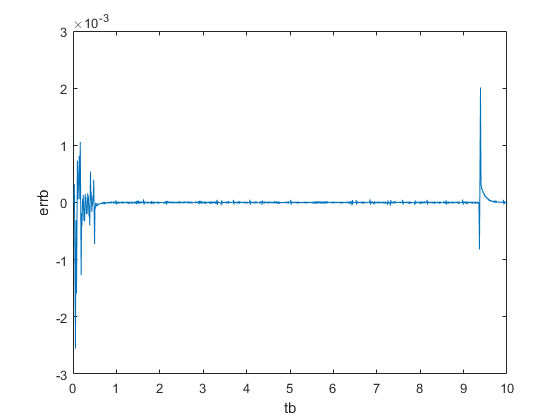

plot(tb,errb);
xlabel('tb'), ylabel('errb');

option = odeset('MaxStep',pi/100);

[tc,yc] = ode45(f,[0,10],1,option);
errc = ye(tc) - yc;
maxerrc = norm(errc,'inf')

maxerrc = 2.2026e-04

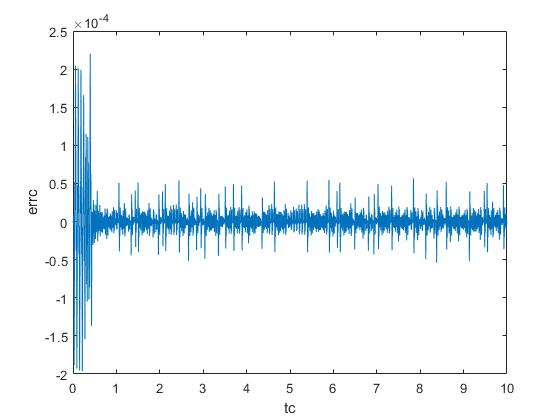

% The error in '1-c' is smaller than in '1-b';

plot(tc,errc);
xlabel('tc'), ylabel('errc')

relvec = 0.000038:-0.000000001:0;
absvec = 0.000038:-0.000000001:0;
i = 1;
while true
    op = odeset('RelTol',relvec(i),'abstol',absvec(i));
    [td,yd] = ode45(f,[0,10],1,op);
    errd = ye(td)-yd;
    maxerrd = norm(errd,'inf');
    if maxerrd <= maxerrc
        break
    end
    i = i+1;
end
reltol = relvec(i)

reltol = 3.3576e-05

abstol = absvec(i)

abstol = 3.3576e-05

maxerrd

maxerrd = 1.9587e-04

maxerrc

maxerrc = 2.2026e-04